# Low-pass & High-pass Filter

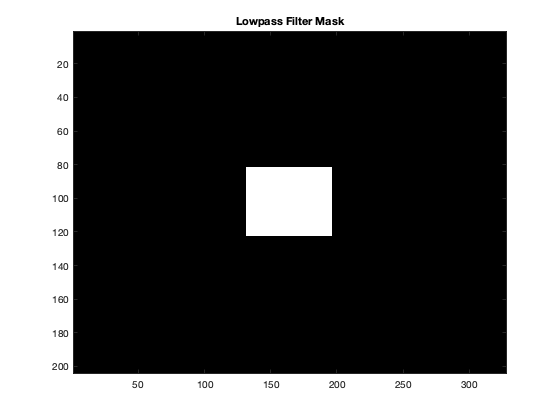

obj = importdata('forclass.mat');
% img_original = obj;
y = size(obj,1);
x = size(obj,2);

% low frequencies at the center 
% coordinates of four corner
xFilter = [x/2-x/10 x/2+x/10 x/2+x/10 x/2-x/10];
yFilter = [y/2+y/10 y/2+y/10 y/2-y/10 y/2-y/10];
lowPass = poly2mask(xFilter,yFilter,y,x);
highPass = ~lowPass;

% Apply LP & HP Filter in Fourier Domain
OBJ = ifftshift(fft2(fftshift(obj)));

IMG(:,:,1) = OBJ .* lowPass;
IMG(:,:,2) = OBJ .* highPass;

img = ifftshift(ifft2(fftshift(IMG)));

figure()
imagesc(lowPass)
colormap bone
title('Lowpass Filter Mask')

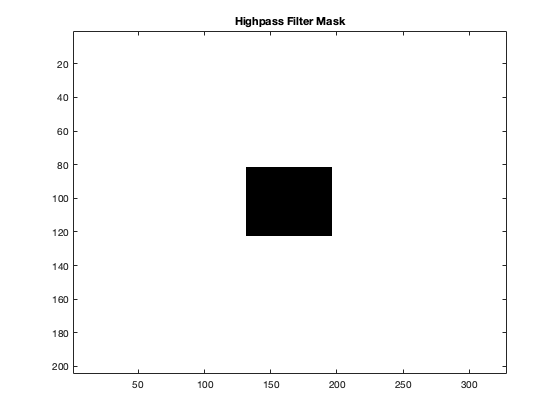


figure()
imagesc(highPass)
colormap bone
title('Highpass Filter Mask')

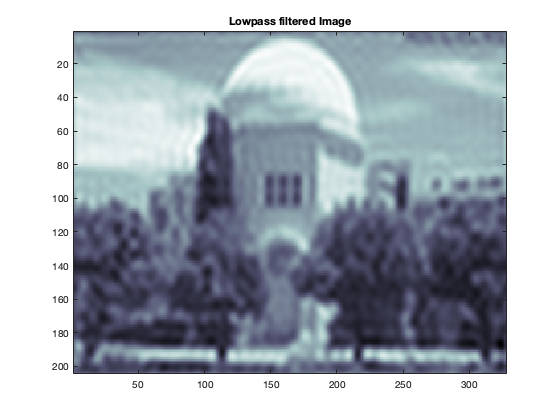


figure()
imagesc(real(img(:,:,1)))
colormap bone
title('Lowpass filtered Image')

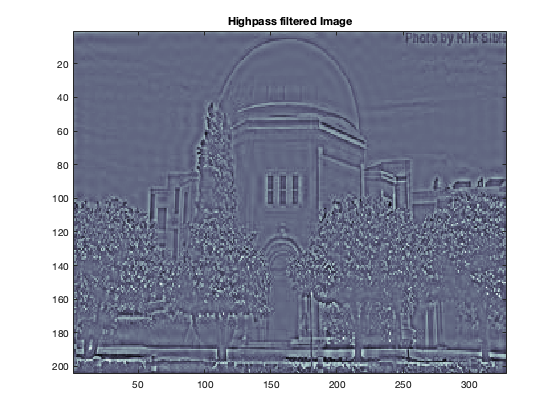


figure()
imagesc(real(img(:,:,2)))
colormap bone
title('Highpass filtered Image')

## Extract the vertical edges

horiz